# Simulazione di un filtro RC con diodo in parallelo.

### MODELING:

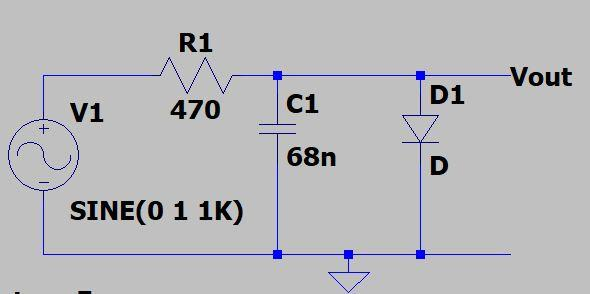

Il circuito è non lineare per cui lo state-space model sarà della forma


$$\dot{x=f\left(x,u\right)}$$



$$y=g\left(x,u\right)$$


Ciò che voglio simulare è l'andamento dell tensione di uscita Vout in risposta all tensione di ingresso. All'interno di questo circuito c'è un solo condensatore e quindi un solo elemento dinamico (ricordiamo che la caratteristica corrente-tensione di un condensatore è 

#### 
$$i_c =C\frac{\mathrm{d}}{\mathrm{d}t}v_c$$


).

Di conseguenza ho una sola variabile di stato.

Scelgo:

-come variabile di stato la tensione sul condensatore x=vc

-come uscita la tensione sul diodo cioè y=vout

-come ingresso la tensione sinusoidale V1 quindi u=V1

Osservando meglio il circuito mi accorgo che la vc è uguale alla vout. Ciò è naturale in quanto condensatore e diodo sono in parallelo. Quindi posso già scrivere l'espressione della seconda equazione dello state.space model come y=x. Ciò significa che per trovare la variabile di nostro interesse dobbiamo solo simulare $\dot{x}$. 

Simulare $\dot{x}$ ci restituisce $x$ e una volta trovato $x$ abbiamo già l'uscita perchè, per questo particolare sistema, y=x.

Ci resta quindi da trovare l'espressione di $\dot{x}$ . Avendo scelto $x$=vc allora $\dot{x}$$=\dot{v_c } =\frac{\mathrm{d}}{\mathrm{d}t}v_c$

Ma dall'espressione sopra $\frac{\mathrm{d}}{\mathrm{d}t}v_c =\frac{i_c }{C}$. Quindi ora basta ricavare $i_c$ e poi dividere tutto per C in modo da ottenere l'equazione per $\dot{x}$.

Per trovare $i_c$ usiamo la prima legge di Kirchhoff al nodo cerchiato in rosso in figura:

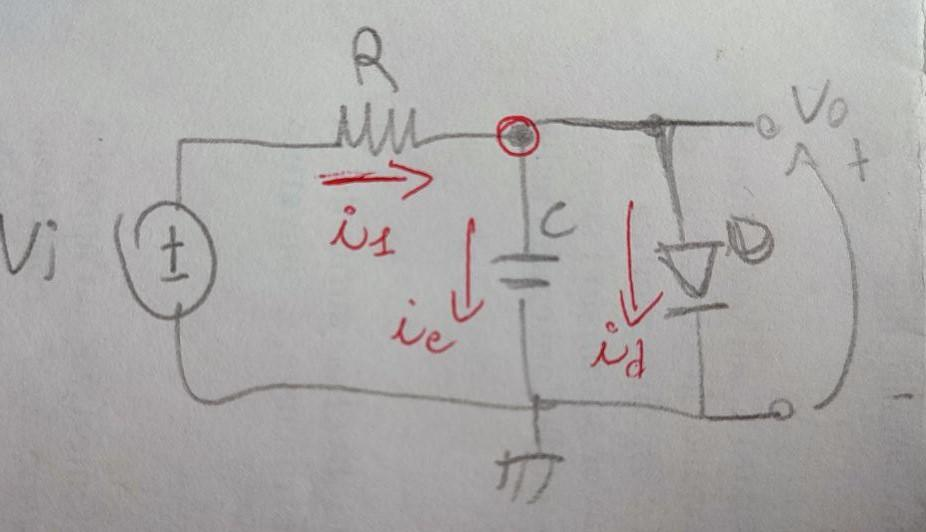

$i_1 =i_c +i_d$ ma allora $i_c =i_1 -i_d$. 

La caratteristica I/V del diodo è: $i_{d=\;} I_s \left(\exp \left(\frac{v_d }{\textrm{vt}}\right)-1\right)=$$I_s \left(\exp \left(\frac{x}{\textrm{vt}}\right)-1\right)$dato che x=vc=vd=vout.

Abbiamo tutto per scrivere $i_c$:

$i_c$=$\frac{V_i -x}{R}-I_s \left(\exp \left(\frac{x}{\textrm{vt}}\right)-1\right)$=$\frac{u-x}{R}-I_s \left(\exp \left(\frac{x}{\textrm{vt}}\right)-1\right)$

Ora basta dividere l'epsressione appena ottenuta per C.

Lo state-space nonlinear model risultante è:


$$\dot{x} =\frac{u-x}{\textrm{RC}}-\frac{\textrm{Is}}{C}\left(\exp \left(\frac{x}{\textrm{vt}}\right)-1\right)$$



$$y=x$$


### MATLAB SIMULATION

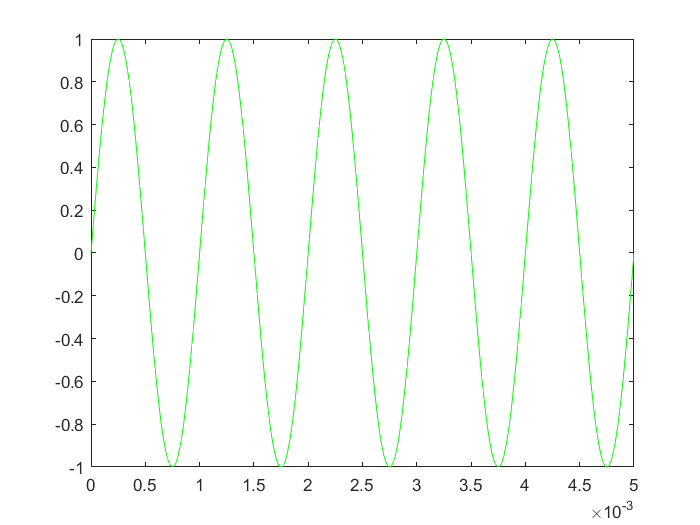

clear,clc


%input signal definition
time=(0:0.00001:5e-3); %time vector of 5ms
u=sin(2*pi*1000*time);  %5ms sinusoid di frequenza 1000 Hz
plot(time,u,'g');




%simulation parameters
tsim = time(end);%il tempo di simulazione è pari alla durata temporale del segnale di ingresso cioè l'ultimo elemento del vettore time
Tstep = 0.00001; %passo di simulazione
ti = 0; %tempo iniziale
Vo = 0; %tensione di uscita iniziale
x = Vo;
omega=2*pi*1000;



% NON-LINEAR MODEL SIMULATION
% I parametri del circuito (ovvero i valori di R,C,Is e vt sono modificabili
% all'interno della funzione xdot_D
while ti<=tsim
    y=x; %calcolo l'uscita usando il valore iniziale e poi con le x(=vout)successive
    u=sin(omega*ti);%mi calcolo il sample della tensione di ingresso
    [tsol,xsol] = ode45(@(t,x) xdot_D(u,x), [ti ti+Tstep], x(:,end));  %ode45 restituisce i vettori tsol e xsol
    x = [x xsol(end,:)'];                                            %x è la matrice che contiene le soluzioni, infatti ad ogni passo prendiamo xsol e lo appendiamo come colonna dentro x
    ti = ti+Tstep;                                                     %aggiorniamo il passo temporale per il prossimo ciclo  
end
%plot(0:Tstep:tsim,x(:,end-1));
hold on
plot(time,y,'r');
title('output signal(red) vs input signal(green)');
xlabel('Time[s]')
ylabel('Vout[V]')


In allegato mostro due plot della risposta di questo circuito su LTspice in modo da confrontare i risulati ottenuti qui su MATLAB.

plot1: (Verde il segnale di ingresso, Rosso segnale di uscita)

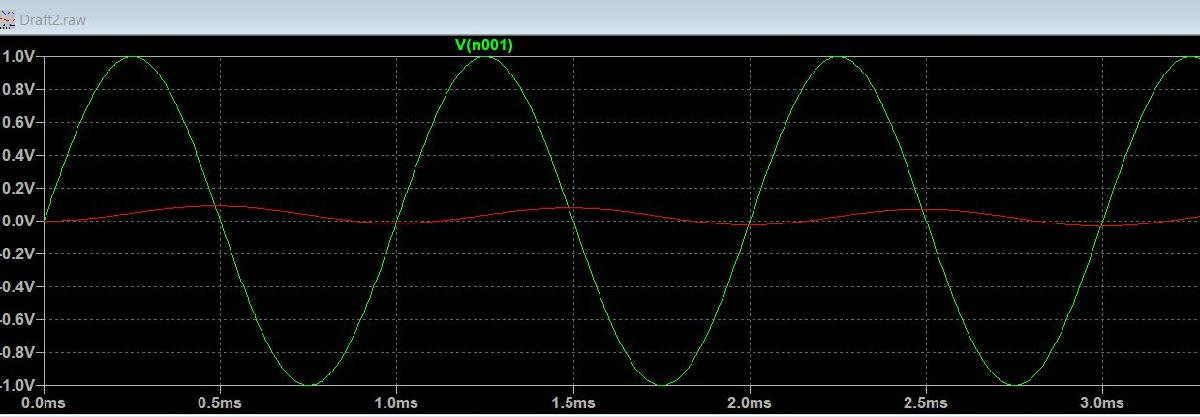

ottenuto usando R=47k, C=68n, sinusoide a frequenza 1kHz.

plot2:(Verde il segnale di ingresso, Rosso segnale di uscita)

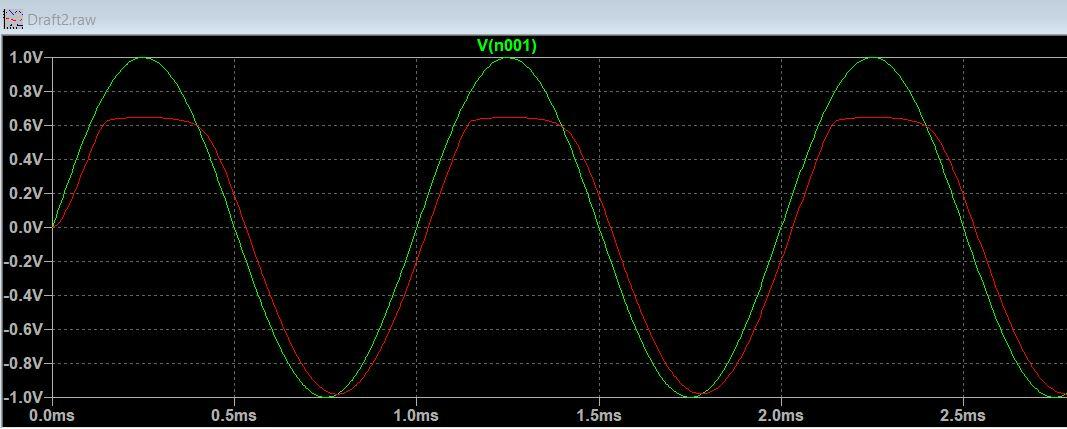

Simulazione realizzata solo cambiando R da 47k a 470 ohm. Come era prevedibile, abbassando la R, la caduta di tensione su quest'ultima risulta minore e quindi stiamo alimentando maggiormente il componente non lineare, cioè il diodo, il quale realizza la distorsione della sinusoide.

Provando a cambiare il valore di R anche qui su MATLAB(nella funzione xdot_D) otteniamo gli stessi risultati.

Piccole discrepanze tra i valori numerici possono essere dovuti a diversi valori di Is e Vt che utilizza LTspice (se proviamo a mettere Is=1e-14 i risultati sono ancora più simili a ciò che vediamo su LTspice) senza considerare che la simulazione di LTspice potrebbe tenere conto anche di capacità parassite ecc...in sostanza potrebbe tenere conto di altri fattori che noi NON abbiamo incluso nel nostro modello. Ciò detto, però, la simulazione risulta comunue molto buona in termini di forma d'onda e valori di picco.